Phenotype Table

phenotypes = readtable("NKI_1_phenotypic_data.csv");
obsolete_cols = get_obs_cols(phenotypes);

session1_phenotypes = phenotypes(strcmp(phenotypes.SESSION, 'Baseline'), :);
s1_obs = get_obs_cols(session1_phenotypes);

session2_phenotypes = phenotypes(strcmp(phenotypes.SESSION, 'Retest_1'), :);
s2_obs = get_obs_cols(session2_phenotypes);

obsolete_cols = obsolete_cols | s1_obs | s2_obs;
phenotypes(:, obsolete_cols) = [];
phenotypes = sortrows(phenotypes, "SUBID")

phenotypes = 48×12 table
      SUBID       AGE_AT_SCAN_1    HANDEDNESS    CURRENT_DIAGNOSIS    LIFETIME_DIAGNOSIS                              CURRENT_DX_1                                    CURRENT_DX_2                   LIFETIME_DX_1                  LIFETIME_DX_2          LIFETIME_DX_3    LIFETIME_DX_4    LIFETIME_DX_5
    __________    _____________    __________    _________________    __________________    ________________________________________________________________    _________________________    _____________________________    _________________________    _____________    _____________    

Network Statistics

network_stats = readtable("resultsDirected-False.csv");

network_stats.Properties.VariableNames{1} = 'subject_id';
network_stats.threshold = categorical(network_stats.threshold);
network_stats = sortrows(network_stats, ["threshold", "subject_id"])

network_stats = 520×12 table
    subject_id    session_number    threshold    density    avg_clst    avg_deg      r2      diameter    num_clq    max_clq_size    max_load_cent    strConnectedComps
    __________    ______________    _________    _______    ________    _______    ______    ________    _______    ____________    _____________    _________________

         21001          1               1         0.465      0.7878       32       0.1924       4          70            30           0.051974               1        
         21001          2               1        0.3793      


thresholds = categories(network_stats.threshold);
conditions = [];
for i = 1:numel(thresholds)
    conditions = [conditions; phenotypes.LIFETIME_DIAGNOSIS(any(network_stats.subject_id == phenotypes.SUBID', 1))];
end
network_stats.condition = conditions

network_stats = 520×13 table
    subject_id    session_number    threshold    density    avg_clst    avg_deg      r2      diameter    num_clq    max_clq_size    max_load_cent    strConnectedComps    condition
    __________    ______________    _________    _______    ________    _______    ______    ________    _______    ____________    _____________    _________________    _________

         21001          1               1         0.465      0.7878       32       0.1924       4          70            30           0.051974               1          

Figures and p_vals

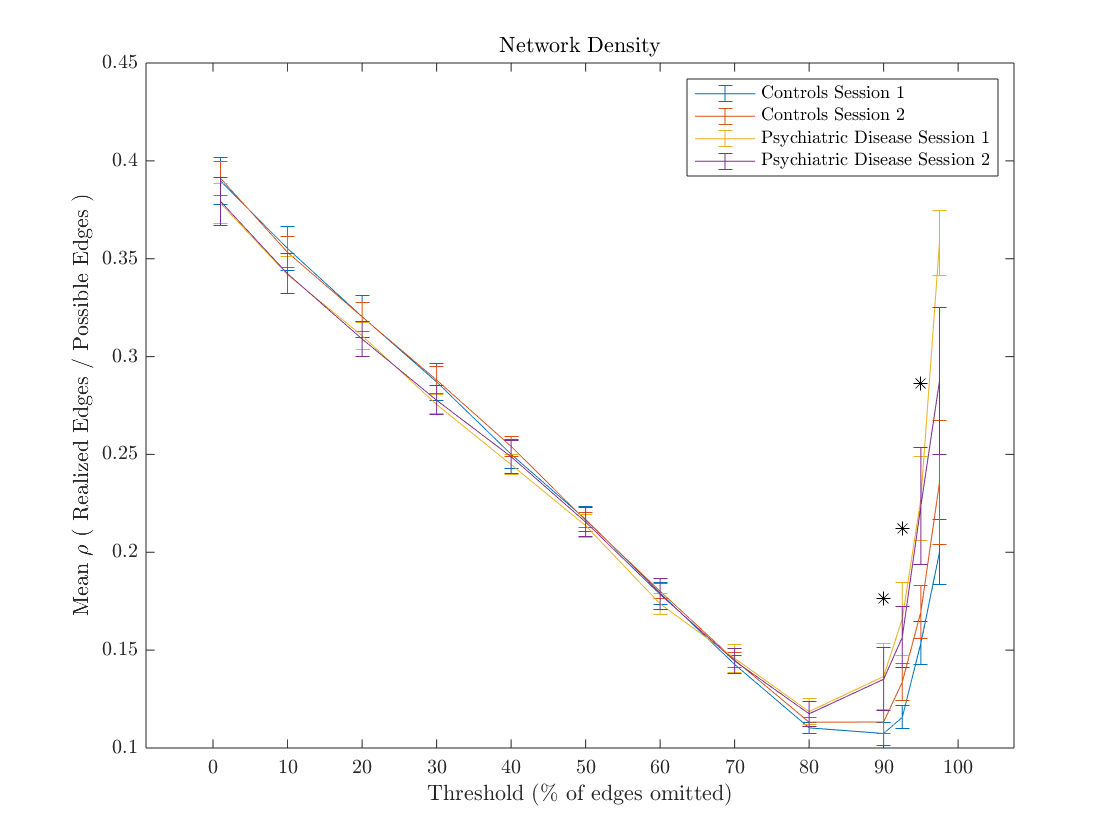

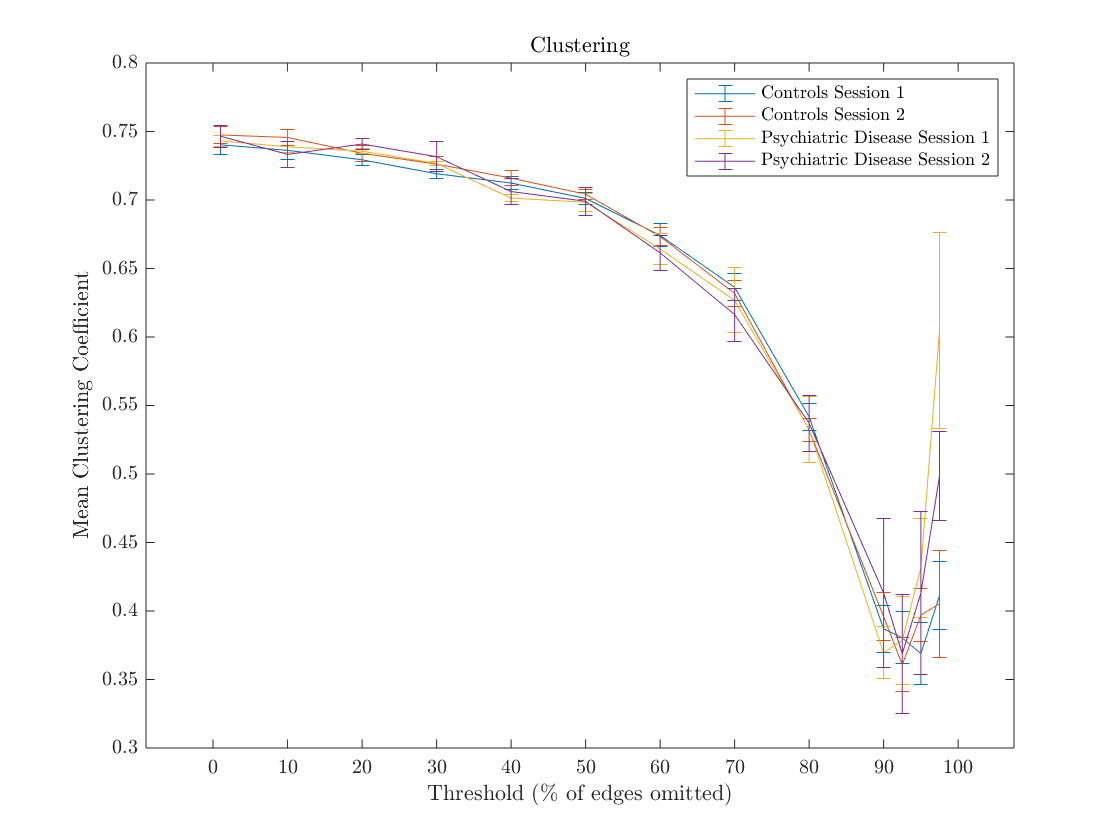

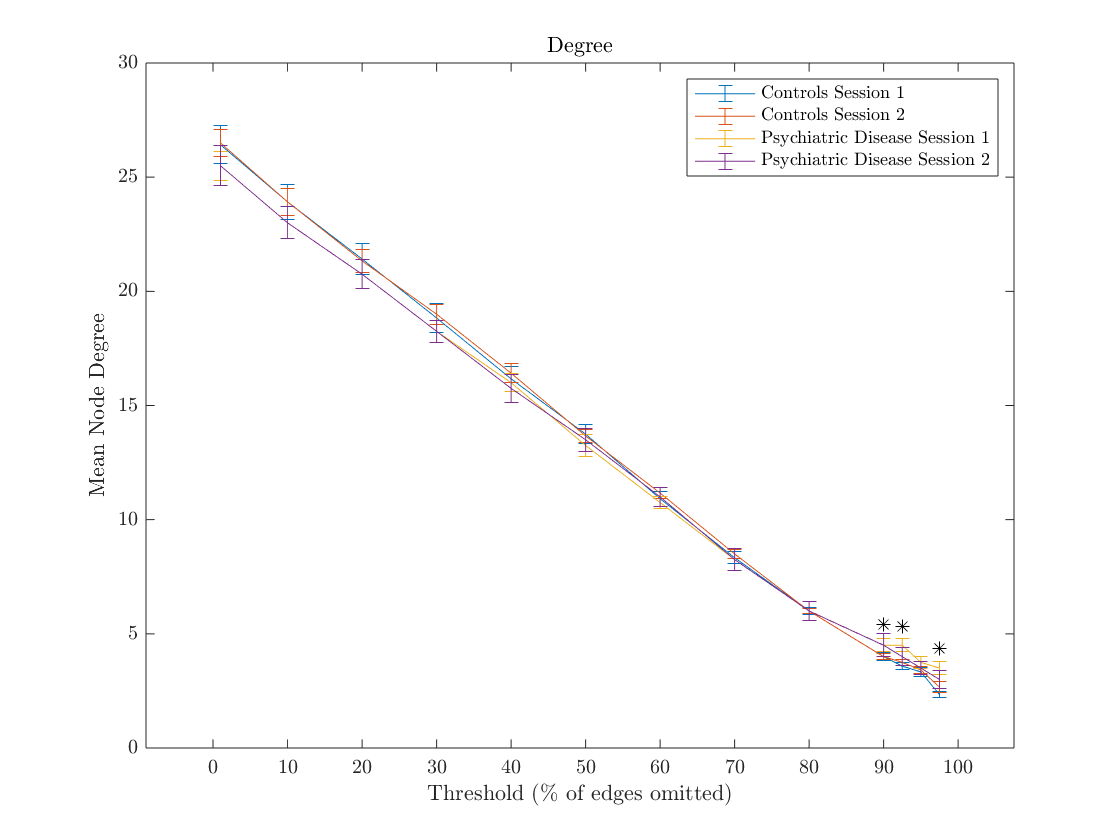

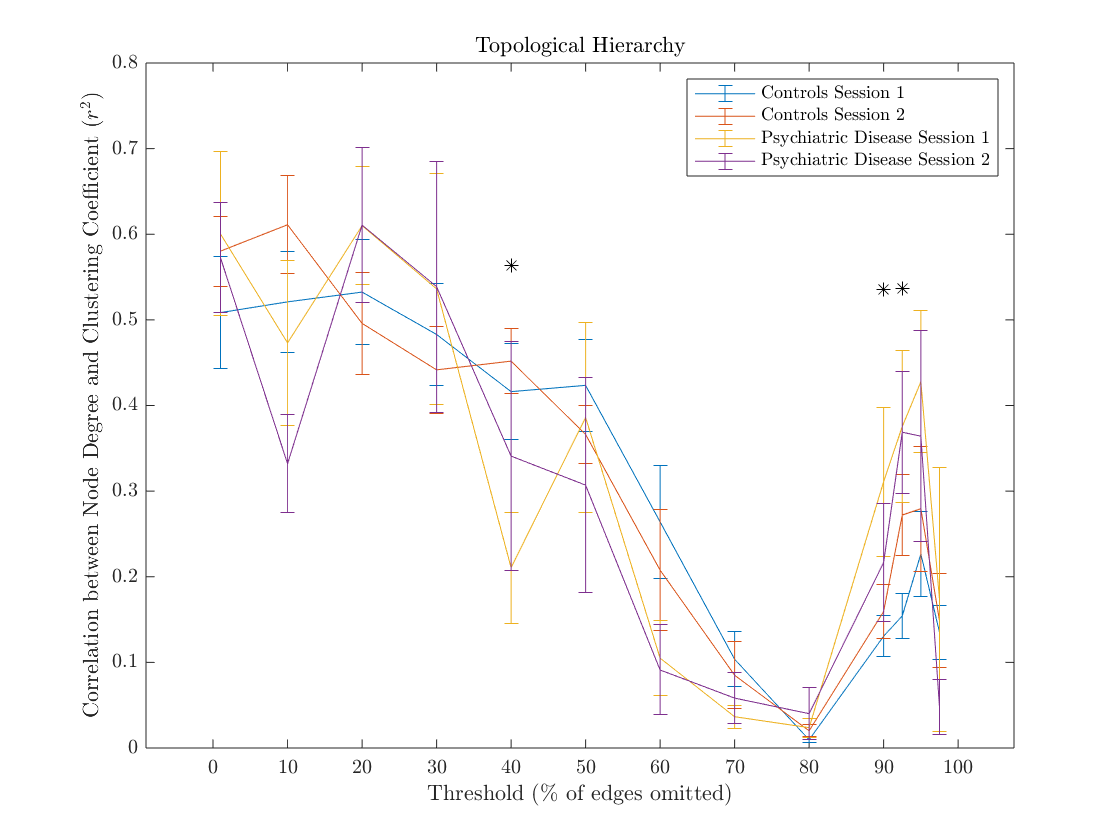

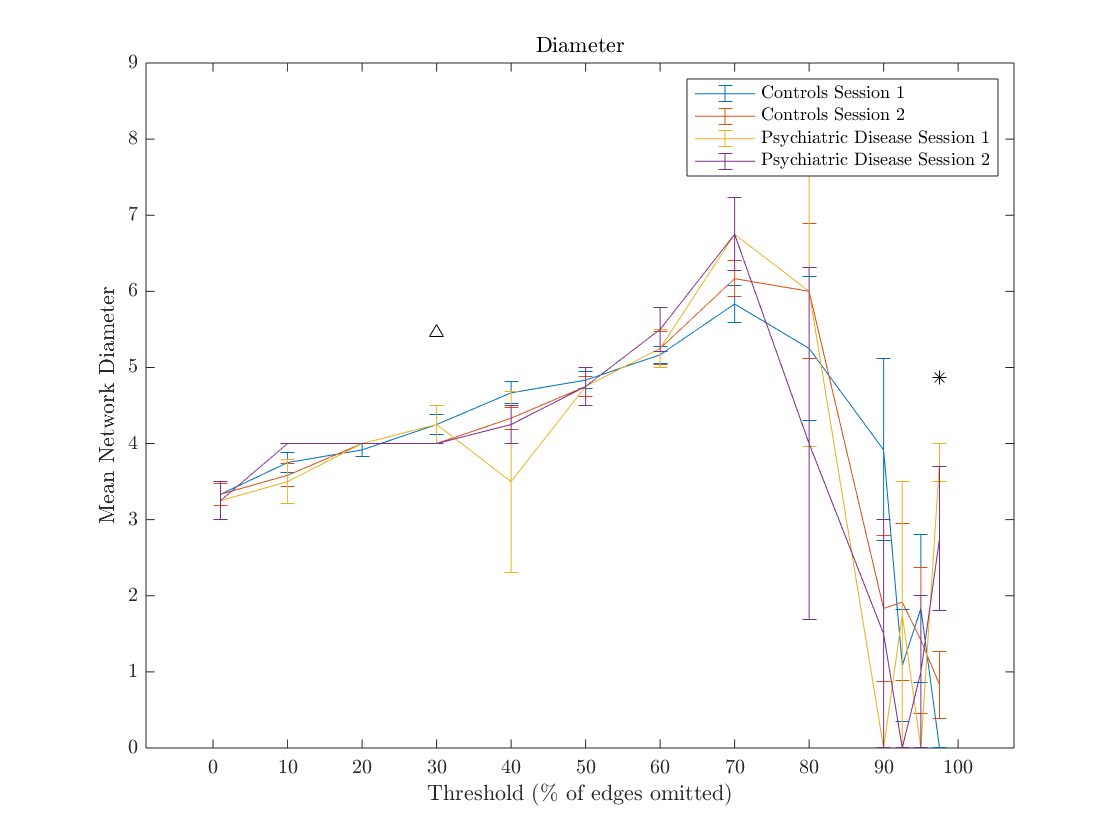

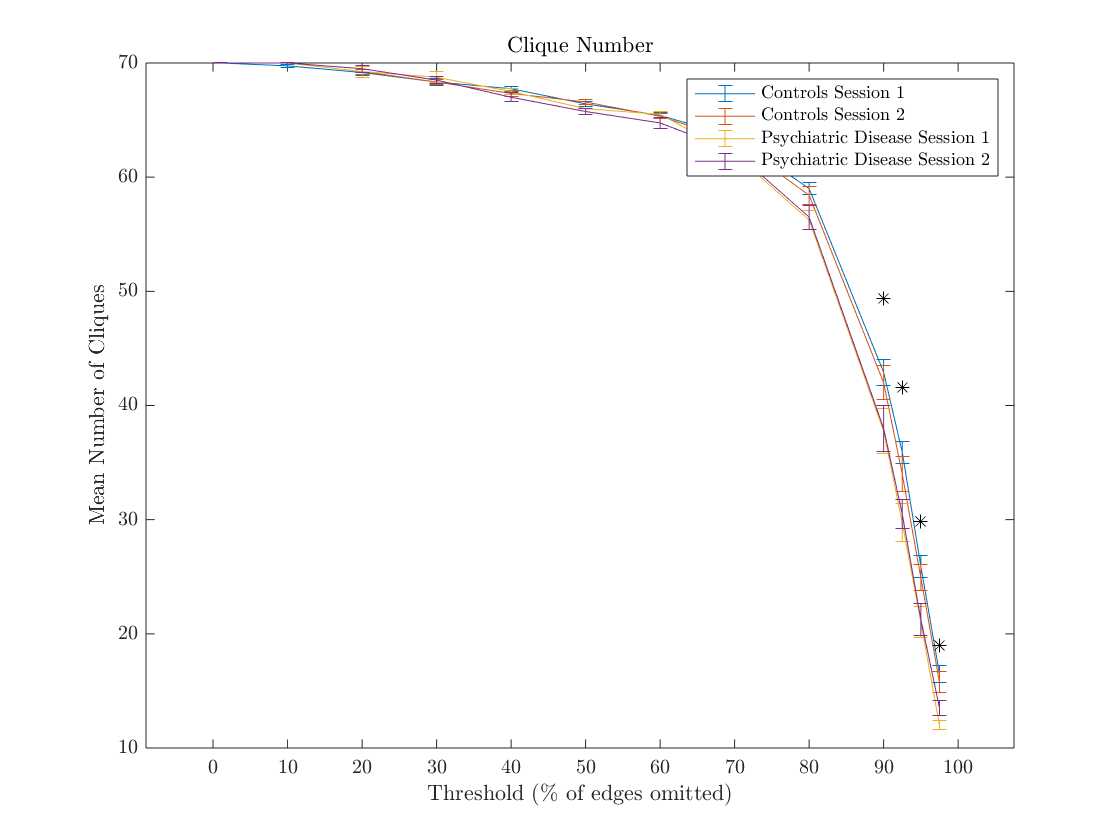

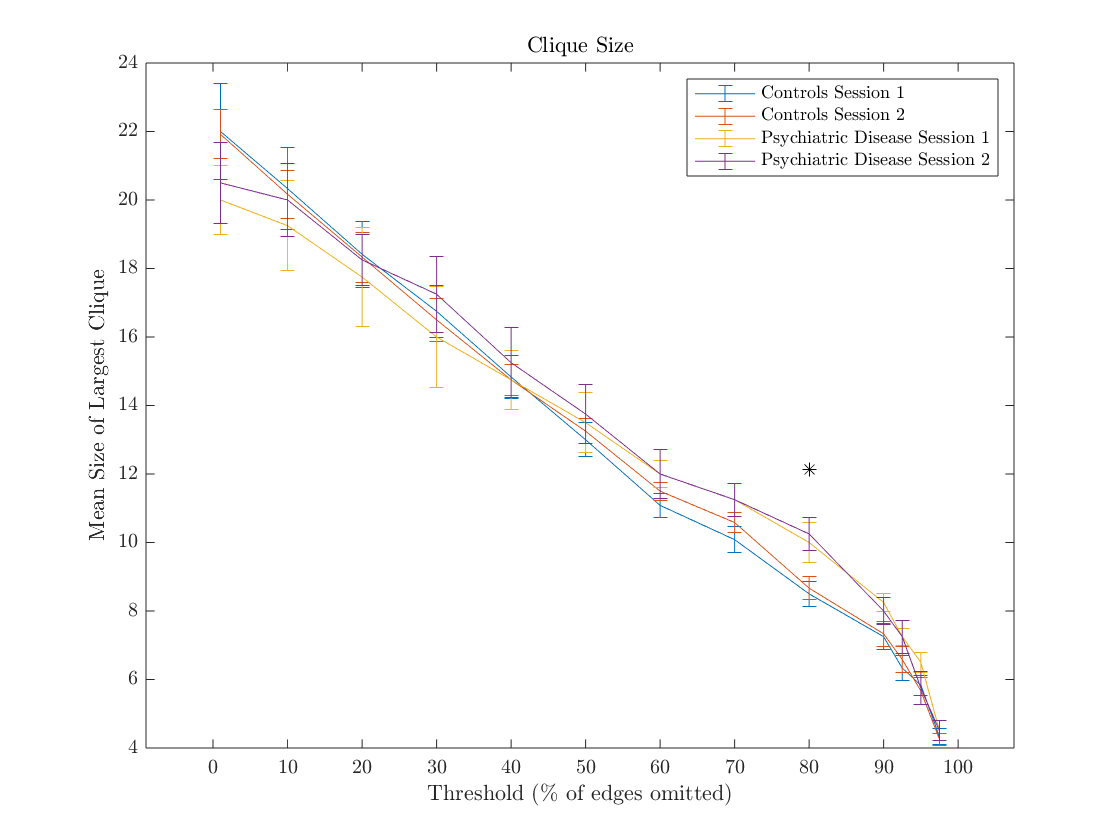

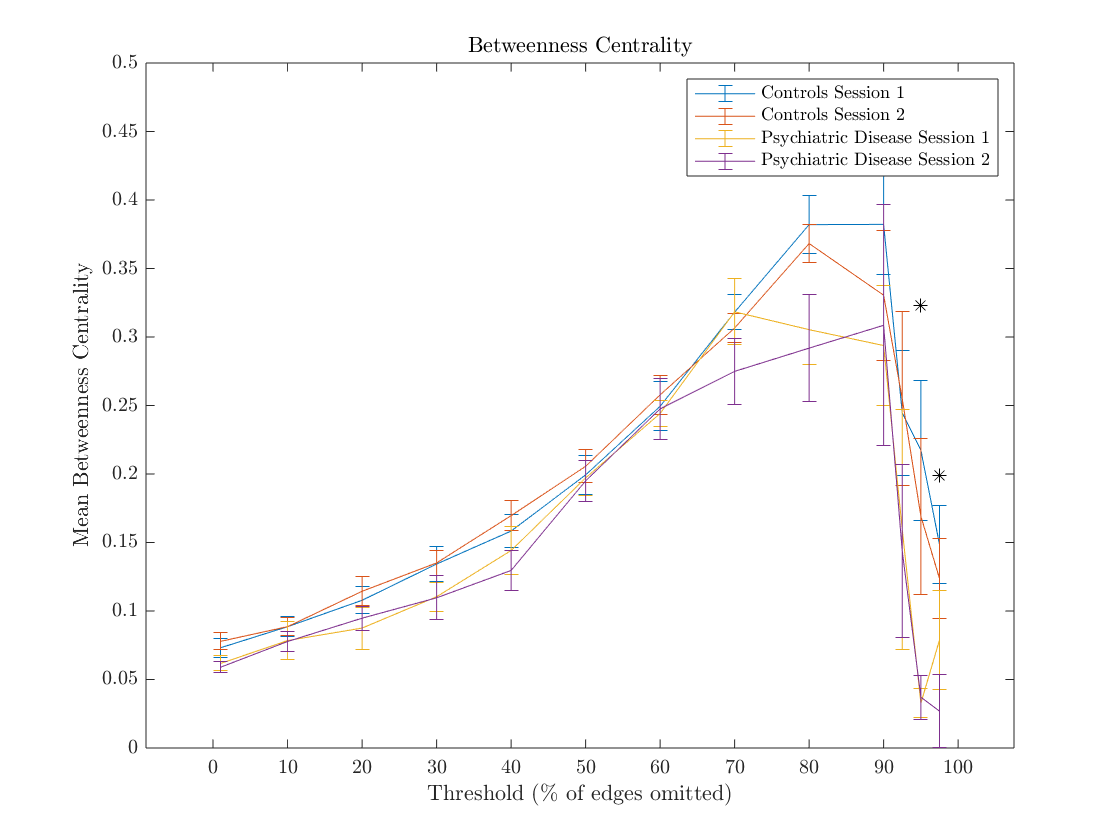

stats = string(network_stats.Properties.VariableNames(4:(end-1)))';
titles = ["Network Density", "Clustering", "Degree", "Topological Hierarchy", "Diameter", "Clique Number", "Clique Size", "Betweenness Centrality", "Components"];
ylabels = ["Mean $\rho$ ( Realized Edges / Possible Edges )", "Mean Clustering Coefficient", "Mean Node Degree", "Correlation between Node Degree and Clustering Coefficient ($r^2$)", "Mean Network Diameter", "Mean Number of Cliques", "Mean Size of Largest Clique", "Mean Betweenness Centrality", "Mean Number of Connected Components"];

p = zeros([numel(thresholds)*numel(stats), 2]);
for i = 1:numel(stats)
    p((1+(i-1)*numel(thresholds)):i*numel(thresholds), :) = plot_netstat(network_stats, stats(i), titles(i), ylabels(i), thresholds);
end


table_stats = [];
table_thresholds = [];
for t = 1:numel(thresholds)
    table_stats = [table_stats; stats];
    table_thresholds = [table_thresholds; ones([numel(stats), 1])*str2double(thresholds(t))];
end
p_session = p(:, 1);
p_condition = p(:, 2);
p_vals = table(table_stats, table_thresholds, p_session, p_condition);
writetable(p_vals, "mlx_graphs/Scatterplots/p_vals.csv", "Delimiter", ",");

Functions

function obs_cols = get_obs_cols(A)
    s = size(A);
    obs_cols = false(1, s(2));
    for col = 1:s(2)
        if isa(A{1, col}, 'cell')
        unique_entries = setdiff(A{:, col}, A{1,col});
        if numel(unique_entries) == 0
            obs_cols(1, col) = 1;
        end
    elseif isa(A{1, col}, "double")
        if all(A{:, col} == A{1, col})
            obs_cols(1, col) = 1;
        end
    end
    end
end

%plotting graphs without unknown category for simplicity
function p = plot_netstat(netstats, stat, stat_title, stat_ylabel, thresholds)
    means = zeros([numel(thresholds), 4]);
    SEMs = zeros([numel(thresholds), 4]);
    p = zeros([numel(thresholds), 2]);
    
    for t = 1:numel(thresholds)
        %Segregate by threshold
        netstats_t = netstats(netstats.threshold == thresholds(t), :);

        %Segregate by condition
        controls = netstats_t(any(strcmp(netstats_t.condition, 'NO'), 2), :);
        psychs = netstats_t(any(strcmp(netstats_t.condition, 'YES'), 2), :);
    
        %Segregate by session number
        control = controls.(stat);
        control_s1 = control(controls.session_number == 1);
        control_s2 = control(controls.session_number == 2);
    
        psych = psychs.(stat);
        psych_s1 = psych(psychs.session_number == 1);
        psych_s2 = psych(psychs.session_number == 2);
    
        %Caluclate means and SEMs
        control_means = [mean(control_s1), mean(control_s2)];
        psych_means = [mean(psych_s1), mean(psych_s2)];
        means(t, :) = [control_means, psych_means];
    
        control_SEMs = [std(control_s1)/sqrt(numel(control_s1)), std(control_s2)/sqrt(numel(control_s2))];
        psych_SEMs = [std(psych_s1)/sqrt(numel(psych_s1)), std(psych_s2)/sqrt(numel(psych_s2))];
        SEMs(t, :) = [control_SEMs, psych_SEMs];
    
        %Obtain p-vals controlling for multiple comparisons
        y = [control; psych];
        g_sesh = [controls.session_number; psychs.session_number];
        g_condition = [controls.condition; psychs.condition];
        p_vals = anovan(y, {g_sesh, g_condition}, "display", "off");
        p_sesh = p_vals(1);
        p_condition = p_vals(2);
        p(t, :) = [p_sesh, p_condition];
    end
    %Plot
    fig = figure();
    thresholds = str2double(thresholds);
    for col = 1:size(means, 2)
        errorbar(thresholds, means(:, col), SEMs(:, col))
        hold on
    end
    sigstar(p, thresholds, means, SEMs);
    set(gca, 'TickLabelInterpreter', 'latex');
    legend(["Controls Session 1", "Controls Session 2", "Psychiatric Disease Session 1", "Psychiatric Disease Session 2"], "Interpreter", "latex");
    title(stat_title, 'Interpreter', "latex");
    ylabel(stat_ylabel, 'Interpreter', "latex");
    xlabel("Threshold (\% of edges omitted)", 'Interpreter',"latex");
    xlim([thresholds(1)-10, thresholds(end)+10])
    hold off
    saveas(fig, "mlx_graphs/Scatterplots/"+stat, 'pdf');
end

function sigstar(p, threshes, means, SEMs)
    SIG_THRESHOLD = 0.05;
    sig_sessions = p(:, 1) < SIG_THRESHOLD;
    sig_conditions = p(:, 2) < SIG_THRESHOLD;
    max_means = max(means, [], 2);
    max_SEMs = SEMs(means == max_means);
    y_cond = (max_means(sig_conditions, :) + max_SEMs(sig_conditions))*1.15;
    y_sesh = (max_means(sig_sessions, :) + max_SEMs(sig_sessions))*1.25;
    
    sig_star = plot(threshes(sig_conditions), y_cond, '*k'); %Significance *
    sig_pound = plot(threshes(sig_sessions), y_sesh, '^k'); %Significance triangle
    
    %To omit from legend
    set(get(get(sig_pound,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
    set(get(get(sig_star,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
end
